Create plots for the paper.

Uses the same **dat3_[variable|fixed]InitEnzyme.mat** data file as **plots_compareHiLowAlpha.mlx**

TODO: try out the new tiledlayout() function for subplotting [may require update to 2019 version]

overwritefiles = true;
%overwritefiles = false;

%clean and prep data
%d = dat(strcmpi('Fixed',dat.mode),:);
%d = d(strcmpi('1x1',d.layouttype),:);
%d = d(d.deathrate==0.00125,:);
%d = d(d.decayrate == 1/120,:);
%d = d(d.costfactor == 1,:);

d = dat3;

figpath = 'C:\sync\biomes\cellulose\optima\data_for_paper\figs\';

%fill out extra columns
%d = populateColumnsForPaper1(d);
%d = cleanupGrowthRate(d);

Section 1: plot cellulose / glucose / enzyme / biomass / growthrate over time for three alphas

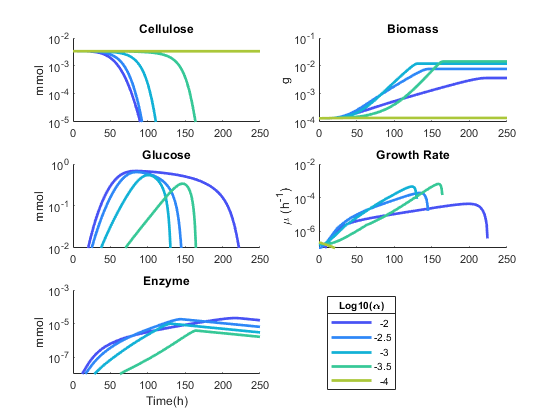

%alphas = pow2([-9 -11 -13]);
alphas = 10.^([-2 -2.5 -3 -3.5 -4]);
d = d(ismember(d.alpha,alphas),:);
d = d(d.celscale == 1,:);
% d.log2alpha = log2(d.alpha);
% d.log10alpha = log10(d.alpha);
d = sortrows(d,'alpha','descend');
varIE = d.variableInitEnzyme(1);
colors = parula(length(alphas)+3);
colors = colors(2:end,:);
%colors = lines(length(alphas));

xmax = 250;
yscale = 'log';
ymins = [1e-5 1e-4 1e-5 1e-7 1e-8]; %constantInitEnzyme
%yscale = 'linear';

f = figure();
hold on;
t = d.t{1};

subplot(3,2,1);
hold on
for i = 1:length(alphas)
    plot(t,d.cellulose_amt{i},'linewidth',2,'color',colors(i,:));
end
hold off;
title('Cellulose');
ylabel('mmol');
xlim([0 xmax]);
set(gca,'yscale',yscale);
if strcmp(yscale,'log')
    if varIE
     ylim([1e-5 1e-2]);
     yticks([1e-5 1e-4 1e-3 1e-2]);
    else
     ylim([1e-5 1e-2]);
     yticks([1e-5 1e-4 1e-3 1e-2]);
    end
end

subplot(3,2,3);
hold on;
for i = 1:length(alphas)
    plot(t,d.glc_amt{i},'linewidth',2,'color',colors(i,:));
end
hold off;
title('Glucose');
ylabel('mmol');
xlim([0 xmax]);
set(gca,'yscale',yscale);
if strcmp(yscale,'log')
    if varIE
     ylim([1e-2 1]);
     %yticks([1e-4 1e-2 1e0]);
    else
     ylim([1e-2 1]);
     %yticks([1e-4 1e-2 1e0]);
    end
end

subplot(3,2,2);
hold on;
for i = 1:length(alphas)
    plot(t,d.biomass{i},'linewidth',2,'color',colors(i,:));
end
hold off;
title('Biomass');
ylabel('g');
xlim([0 xmax]);
set(gca,'yscale',yscale);
if strcmp(yscale,'log')
    if varIE
     ylim([1e-4 1e-1]);
     yticks([1e-4 1e-3 1e-2 1e-1]);
    else
     ylim([1e-4 1e-1]);
     yticks([1e-4 1e-3 1e-2 1e-1]);
    end
end

subplot(3,2,5);
hold on;
for i = 1:length(alphas)
    plot(t,d.enzyme_amt{i},'linewidth',2,'color',colors(i,:));
end
hold off;
title('Enzyme');
ylabel('mmol');
xlim([0 xmax]);
xlabel('Time(h)');
set(gca,'yscale',yscale);
if strcmp(yscale,'log')
    if varIE
     ylim([1e-9 1e-4]);
     yticks([1e-8 1e-6 1e-4]);
    else
     ylim([1e-8 1e-3]);
     yticks([1e-7 1e-5 1e-3]);
    end
end

subplot(3,2,4);
hold on;
for i = 1:length(alphas)
    bio = d.biomass{i};
    biodelta = bio(2:end) - bio(1:end-1);
    plot(t(1:end-1),biodelta,'linewidth',2,'color',colors(i,:));
end
hold off;
title('Growth Rate');
ylabel('\mu (h^-^1)');
xlim([0 xmax]);
set(gca,'yscale',yscale);
if strcmp(yscale,'log')
    if varIE
     ylim([1e-7 1e-2]);
     yticks([1e-6 1e-4 1e-2]);
    else
     ylim([1e-7 1e-2]);
     yticks([1e-6 1e-4 1e-2]);
    end
end

subplot(3,2,6);
hold on;
for i = 1:length(alphas)
    plot(NaN,NaN,'LineWidth',2,'color',colors(i,:));
end
hold off;
leg = legend(num2str(log10(alphas')),'location','west');
set(gca,'Visible','off');
title(leg,'Log10(\alpha)');
hold off;

%save the figure
if overwritefiles
    savefig(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\exampletimeseries.fig','compact');
    saveas(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\exampletimeseries.png');
    saveas(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\exampletimeseries.eps');%for LaTeX
end